# Lab 7 sessió 2

## Segmentació assistida

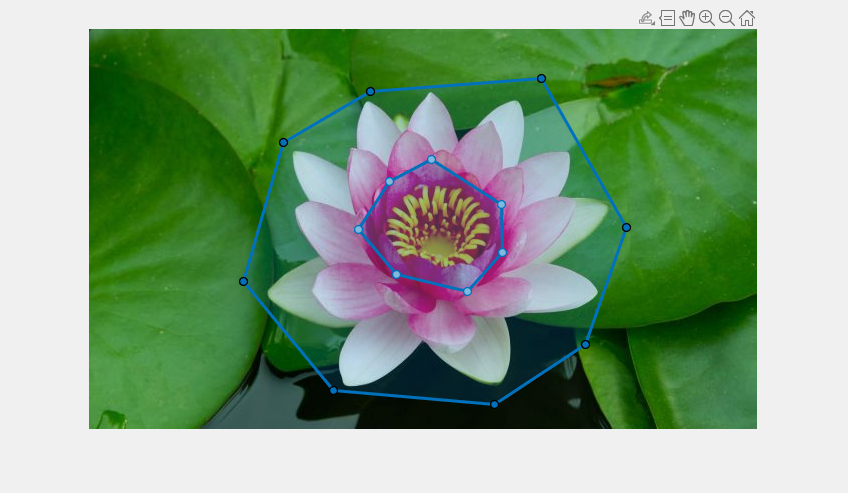

I = imread('nenufar.jpg');
imshow(I);

% roiPoints = drawpolygon;
% d1 = poly2mask(roiPoints.Position(:, 1), roiPoints.Position(:, 2), size(I, 1), size(I, 2));
% roiPoints = drawpolygon;

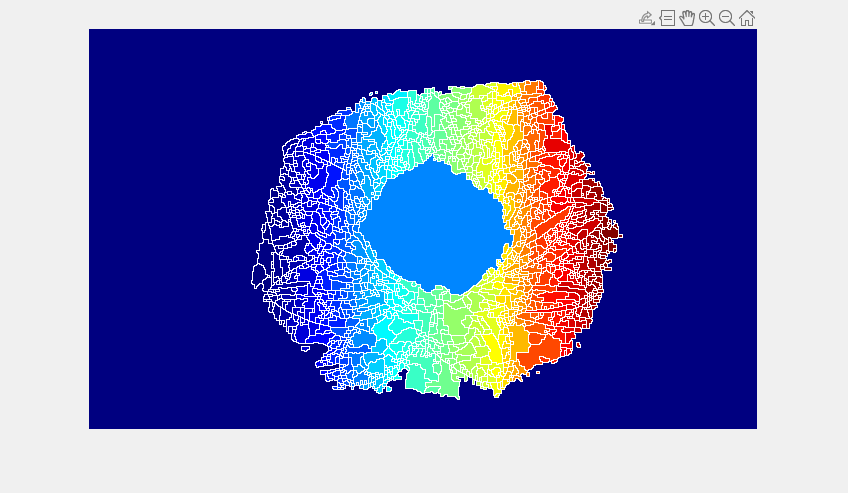

% d2 = poly2mask(roiPoints.Position(:, 1), roiPoints.Position(:, 2), size(I, 1), size(I, 2));
% d3 = poly2mask(roiPoints.Position(:, 1), roiPoints.Position(:, 2), size(I, 1), size(I, 2));

% MASK = not(d1) | d2;

G = imgradient(rgb2gray(I));
IRM = imregionalmax(rgb2gray(I));

N = imimposemin(G, MASK | IRM);

WS = watershed (N);
imshow(label2rgb(WS));

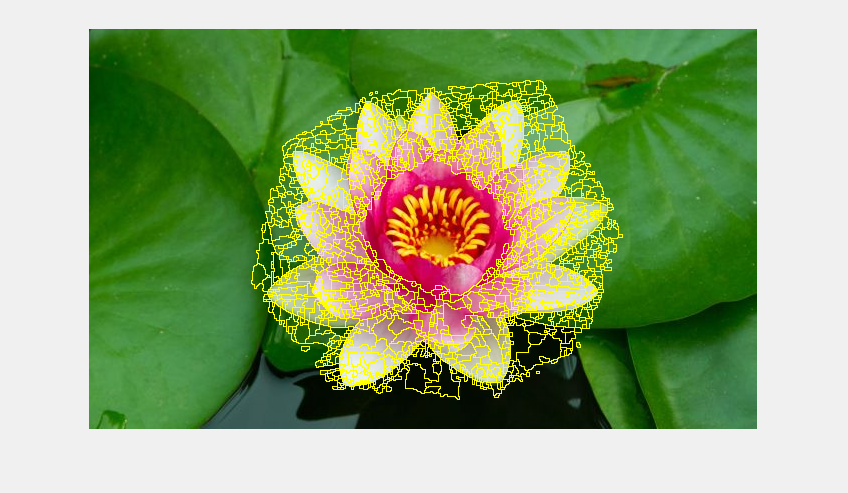


IB = WS == 0;
X = imoverlay(I, IB);
imshow(X);

## Segmentació per kmeans

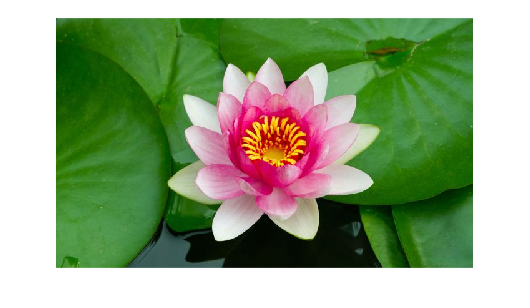

% Reduir el nombre de colors d'una imatge
I = imread('nenufar.jpg');
imshow(I);

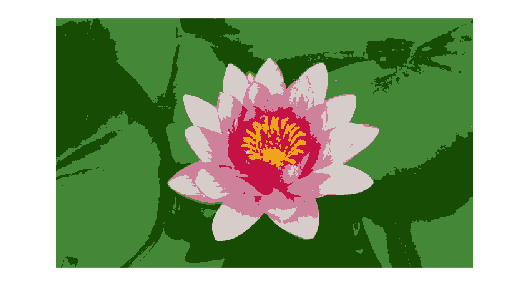


R = I(:, :, 1);
G = I(:, :, 2);
B = I(:, :, 3);

O = [R(:), G(:), B(:)];

N_colors = 6;

[C, CEN] = kmeans(double(O), N_colors);

C = reshape(C, [f, c]);

[f, c, p] = size(I);
RGB2 = uint8(zeros(f,c,p));

for i = 1 : f
    for j = 1 : c
        RGB2(i, j, 1) = uint8(CEN(C(i,j), 1));
        RGB2(i, j, 2) = uint8(CEN(C(i,j), 2));
        RGB2(i, j, 3) = uint8(CEN(C(i,j), 3));
    end
end

imshow(RGB2);

## Automated graph cut through graph min cut

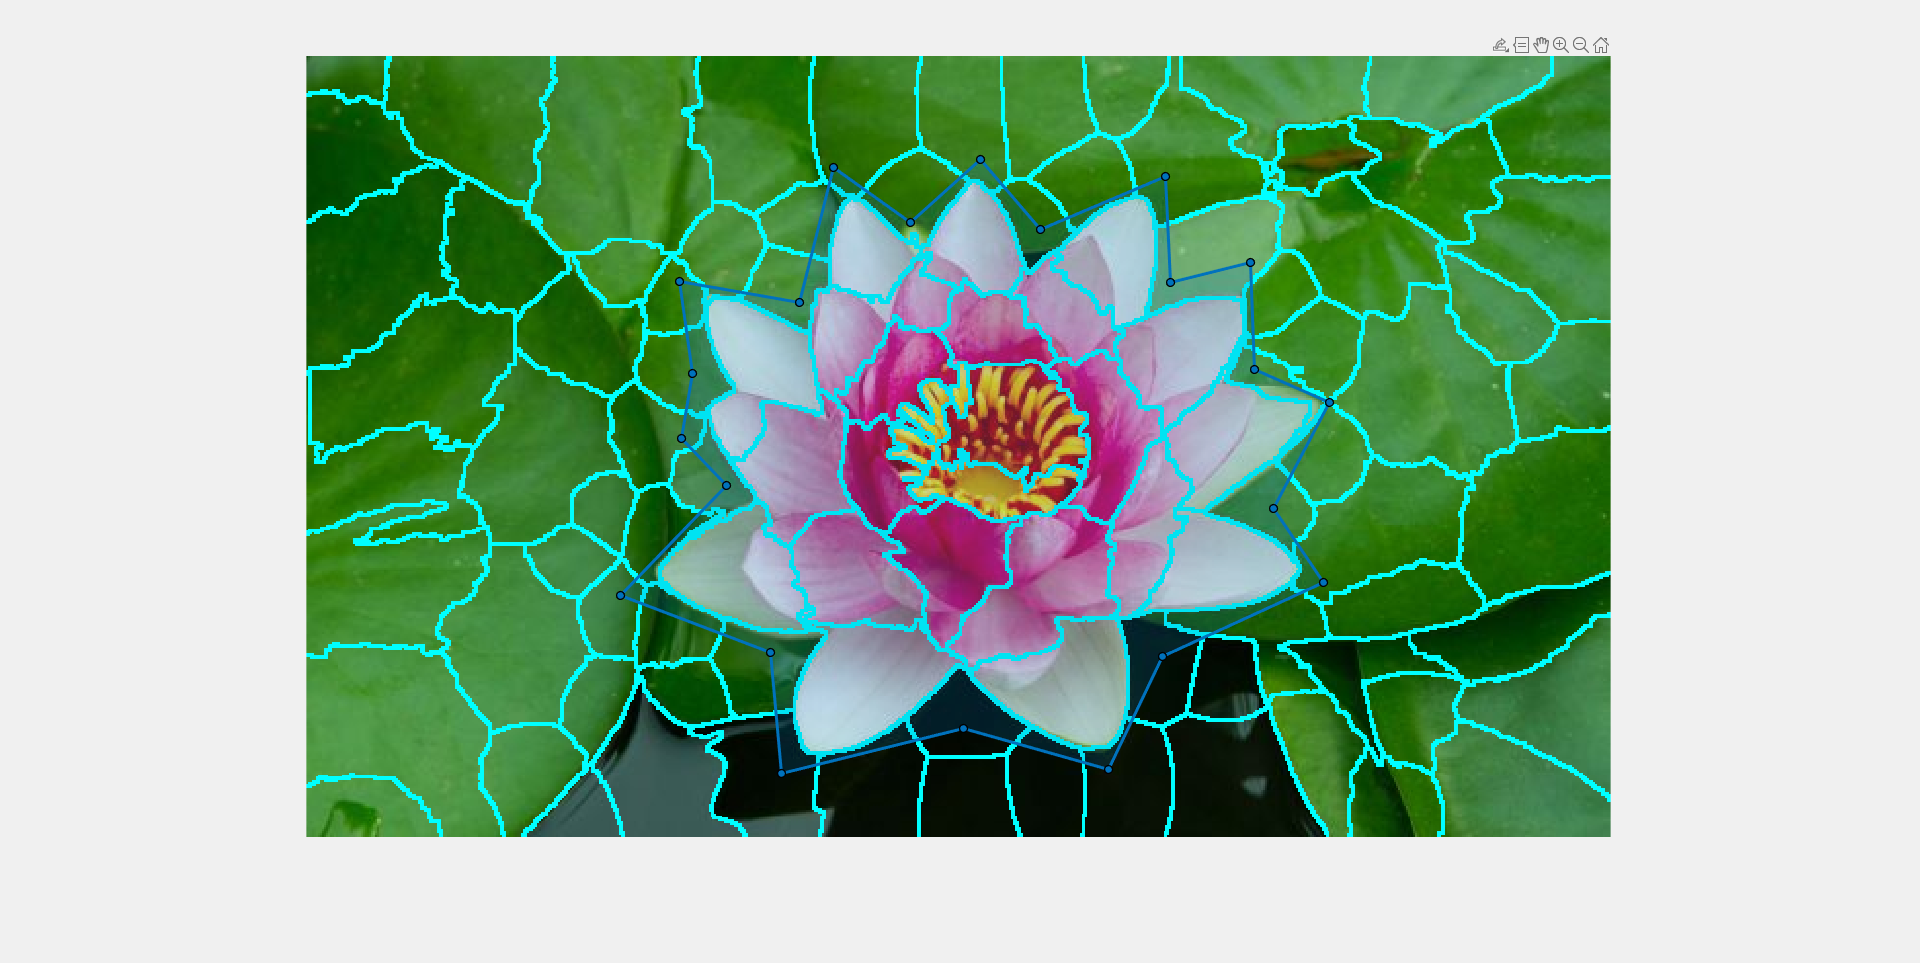

I = imread('nenufar.jpg');
[SP, N] = superpixels(I, 100);

BW = boundarymask(SP);
imshow(imoverlay(I, BW, 'cyan'));

roiPoints = drawpolygon;

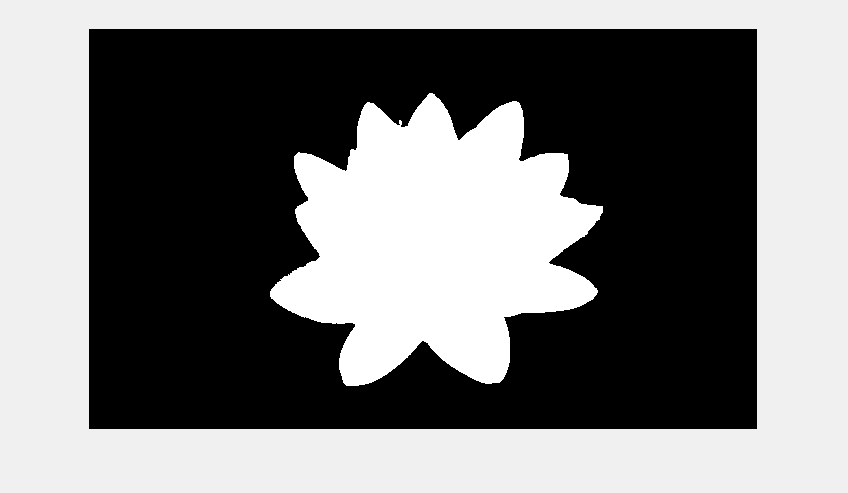

roi = poly2mask(roiPoints.Position(:, 1), roiPoints.Position(:, 2), size(SP, 1), size(SP, 2));
BW = grabcut(I, SP, roi);
imshow(BW);

## Exercici

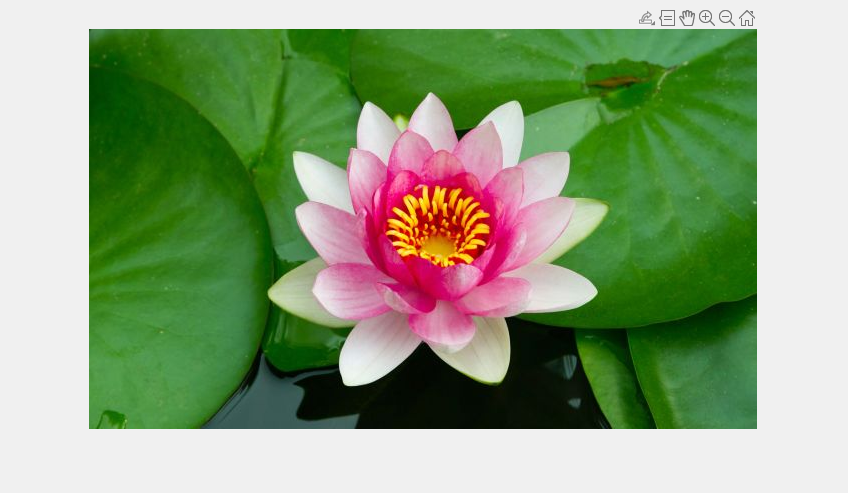

I = imread('nenufar.jpg');
imshow(I);

% Definim una roi rectangular
rect = getrect;

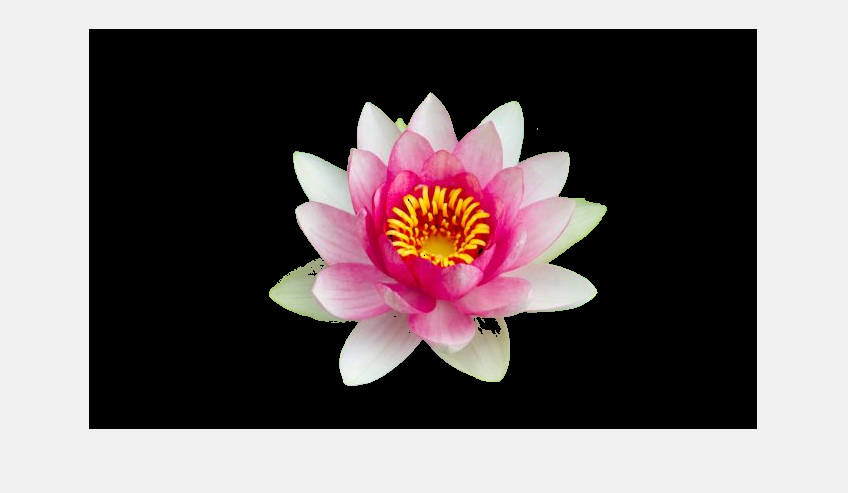

xmin = rect(1); ymin = rect(2);
sizexR = rect(3); sizeyR = rect(4);

R = I(:,:,1); G = I(:,:,2); B = I(:,:,3);
O = [R(:), G(:), B(:)]; % Observacions

 % Classificació per classes (per cada píxel diu a quina classe pertany)
N_colors = 6;
[C, CEN] = kmeans(double(O), N_colors, 'MaxIter', 200);

% Procediment per comptar etiquetes
N_colors = max(C);
[f, c, p] = size(I);
C = reshape(C, [f c]);

count_dins = zeros(N_colors, 1);
count_out = zeros(N_colors, 1);
for i = 1:f
    for j = 1:c
        etiqueta = C(i, j);
        if (i > ymin && i < ymin+sizeyR && j > xmin && j < xmin+sizexR)
            count_dins(etiqueta) = count_dins(etiqueta) + 1;
        else
            count_out(etiqueta) = count_out(etiqueta) + 1;
        end
    end
end

counter = count_dins > count_out;
J = uint8(zeros(f, c, p));
for i = 1:f
    for j = 1:c
        etiqueta = C(i, j);
        if (counter(etiqueta))
            J(i, j, :) = I(i, j, :);
        end
    end
end

imshow(J);